Companion software for "Volker Ziemann, *Hands-on Accelerator physics using MATLAB, CRCPress, 2019*" (https://www.crcpress.com/9781138589940)

# Longitudinal bunch tomography (Section 5.4)

Volker Ziemann, 211112, CC-BY-SA-4.0

**Important:** requires the Statistics and Machine-learning Toolbox (for `hist3`).

**Important:** requires the elliptic package from [https://github.com/moiseevigor/elliptic](https://github.com/moiseevigor/elliptic) located in a subdirectory below the present one (for the fast evaluation of elliptic functions).

In tomographic reconstructions one recovers an approximation of a higher-dimensional distribution from projections in lower dimensions. Here we use one-dimensional projections of the longitudinal distribution--the bunch shape--and try to recover the two-dimesnional distribution.

In the first part of this simulation we record twenty snapshots of a longitudinal particle distribution (in phase only) taken at times $T_s/20$ apart, where $T_s$ is the small-amplitude synchrotron period. In practice these projections could be recordings of a position-monitor sum signal on a fast oscilloscope. In the second part we back-propagate the projections, taken at time $m T_s/20$ with $m=0$ to $19$ to time $0$ and superimpose them. Since we do not know the momentum distribution at the time of the recording, we simply assume that the momenta are evenly distributed, which will show up as bands in the reconstruction, but all these bands overlap in the region, where the initial particle distribution was located, which is thereby recovered.

## Making the projections

We first add the path to the elliptic functions and define some parameters of the simulation. Then we define an initial distribution with center x0 and width dx and plot it as a cloud of green dots in the upper subplot.

clear all; close all
addpath ./elliptic
Omegas=0.25; Ts=2*pi/Omegas; dt=0.05*Ts;
nstep=20;                    % number of projections to record
xbins=-pi:pi/128:pi;         % binning of the projections
N=1000;                      % number of particles
x0=[1.0,0.3]; dx=[0.3,0.1];  % center and spread of distribution
x1=zeros(N,2); 
for k=1:N  % initial distribution
  x1(k,:)=x0+(rand(1,2)-0.5).*dx; 
end
subplot(2,1,1);
plot(x1(:,1),x1(:,2),'g.')
title('Initial distribution')
axis([-pi,pi,-0.67,0.67]);
set(gca,'xtick',[-pi,-pi/2,0,pi/2,pi],'fontsize',14, ...
    'xticklabels',{'-\pi','-\pi/2','0','\pi/2','\pi'})

In the lower subplot we display the projection of the initial distribution onto the phase axis, which is what a BPM sum signal would show, provided the bandwidth of the electronics is very high.

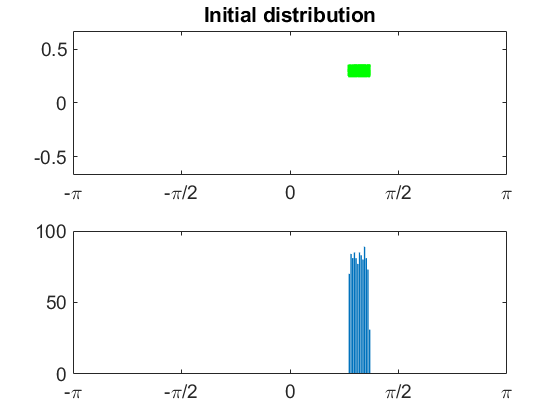

projections=zeros(length(xbins),nstep); % allocate space
projections(:,1)=hist(x1(:,1),xbins);   % save initial projection
subplot(2,1,2); bar(xbins,projections(:,1)); xlim([-pi,pi])
  set(gca,'xtick',[-pi,-pi/2,0,pi/2,pi],'fontsize',14, ...
     'xticklabels',{'-\pi','-\pi/2','0','\pi/2','\pi'})

Now we a ready to propagate the particle distribution for the time dt=Ts/20, plot the distribution in phase space in the upper subplot and use hist() to calculate the projection onto the phase axis and subsequently display it in the lower subplot.

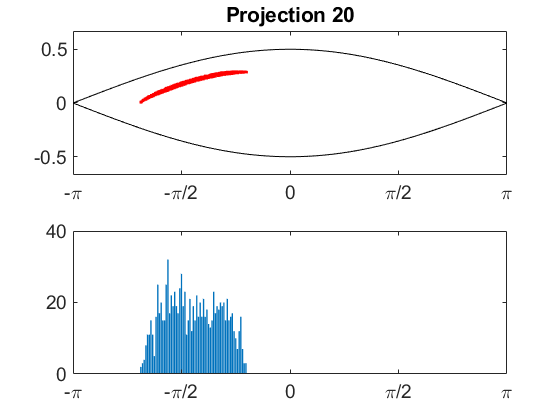

figure
for m=1:nstep-1
  subplot(2,1,1); hold off; 
  phi=-pi:0.01:pi; separatrix=2*Omegas*cos(0.5*phi);
  plot(phi,separatrix,'k',phi,-separatrix,'k');
  title(['Projection ',num2str(m+1)])
  hold on
  parfor k=1:N 
    x1(k,:)=pendulumtracker(x1(k,:),Omegas,dt);
  end
  plot(x1(:,1),x1(:,2),'r.')
  axis([-pi,pi,-0.67,0.67]);
  set(gca,'xtick',[-pi,-pi/2,0,pi/2,pi],'fontsize',14, ...
     'xticklabels',{'-\pi','-\pi/2','0','\pi/2','\pi'})
  projections(:,m+1)=hist(x1(:,1),xbins);  % save projection
  subplot(2,1,2); bar(xbins,projections(:,m+1)); xlim([-pi,pi])
  set(gca,'xtick',[-pi,-pi/2,0,pi/2,pi],'fontsize',14, ...
     'xticklabels',{'-\pi','-\pi/2','0','\pi/2','\pi'})
  pause(0.001)
end

Once we filled the array projections() we simply write it into a data file. 

dlmwrite('projections.dat',projections,'\t');

At this point we have recorded synthetic data from our toy system, but we could equally well save real data into a file with the same format and anlyze that  in the next step.

## Analyzing the projections

In order to obviously make this part self-contained we simply clear the work space, add the path to the elliptic functions and define the same parameters as in the first part. Then we read the file with the saved projections.

clear all; close all
addpath ./elliptic
Omegas=0.25; Ts=2*pi/Omegas; dt=0.05*Ts;  % must match values in
xbins=-pi:pi/128:pi; nbin=length(xbins);  % the above function
projections=dlmread('projections.dat');
nstep=size(projections,2); 

At this point we make an assumption about our ignorance of the momentum distribution while recording the projections. The above-mentioned smearing out in the momentum dimension is specified by `dp`. We also allocate space for the image `im` to which we add all back-propagated projections.

dp=-1:0.01:1; dpbin=length(dp);  % the vertical "spread"
im=zeros(nbin,dpbin);            % reconstructed initial phase space image

Now `m` loops over all the recorded projections and `kbin` over each bin of the projection. If the bin is empty, we just continue with the next one, otherwise we 'spread out' the particles in the` dp` bins with different momentum values and store these `dpbin` starting values in `x1`. Since all these starting values are independent, we can use `parfor` to use all processor-cores to back-propagate the particles to their starting time. Here `hist3() `is a very efficient way to sort these positions into the array im, which provides a continuously improving approximation of the initial distribution that we display with `contourf()` and annotate the axes.

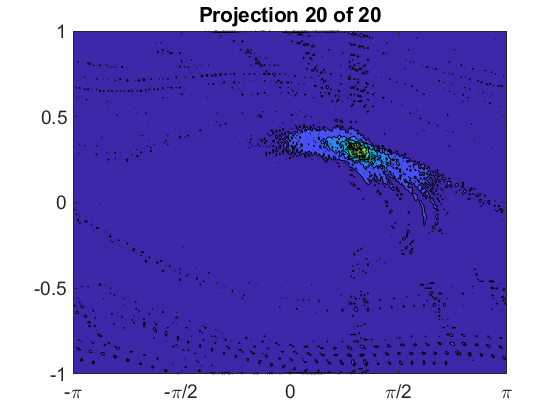

for m=1:nstep
  for kbin=1:nbin
    if projections(kbin,m)==0, continue; end; % abort, if empty
    x1=[xbins(kbin)*ones(dpbin,1),dp'];
    parfor n=1:dpbin  % spread out "vertically"
      x1(n,:)=pendulumtracker(x1(n,:),Omegas,-(m-1)*dt); % back-propagate
    end
    im=im+hist3(x1,{xbins,dp})*projections(kbin,m); % add to image
  end
  contourf(xbins,dp,im')
  set(gca,'xtick',[-pi,-pi/2,0,pi/2,pi],'fontsize',14, ...
     'xticklabels',{'-\pi','-\pi/2','0','\pi/2','\pi'})
  title(['Projection ',num2str(m),' of ',num2str(nstep)]);
  pause(0.2)
end

Now we can calculate the projections of the image im onto the respective axes and can, for example, compare the upper subplot with the initial distribution, shown at the start of the simulation by the green cloud of dots.

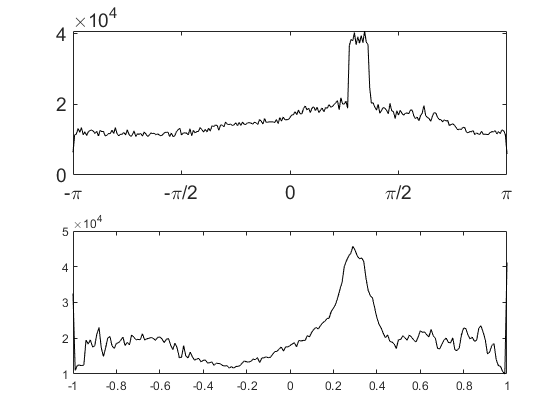

figure(2); % display the projections
subplot(2,1,1); plot(xbins,sum(im,2),'k'); xlim([-pi,pi]);
set(gca,'xtick',[-pi,-pi/2,0,pi/2,pi],'fontsize',14, ...
     'xticklabels',{'-\pi','-\pi/2','0','\pi/2','\pi'})
subplot(2,1,2); plot(dp,sum(im,1),'k')

Now play with the simulation by increasing the number `nstep` of recorded projections, the definition of the momentum-smearing `dp`, or any other parameter.

## Appendix 

The function` pendulumtracker()` receives the phase-space coordinates `x` at the start, the small-amplitude synchrotron frequency `omega`, and the integration time `dt` as input and returns the phase-space coordinates `xout`. Internally, it integrates the equations of motion for a mathematical pendulum in closed form using Jacobi elliptic functions. This is much faster than numerically integration, expecially for extremely large times, such as thousands or even millions of synchrotron periods. The coding closely follows Section 5.4, especially Equations 5.50 to 5.54. Here we use the elliptic functions from [https://github.com/moiseevigor/elliptic](https://github.com/moiseevigor/elliptic).

function xout=pendulumtracker(x,omega,dt)
k2=(0.5*x(2)/omega)^2+sin(0.5*x(1))^2; k=sqrt(k2);
if (x(1)>pi) x(1)=x(1)-2*pi; end
if (x(1)<-pi) x(1)=x(1)+2*pi; end
s=1; if (x(1)<0) s=-s; x(1)=-x(1); end
s1=1; if (x(2)<0) s1=-s1; end
if (k>1)   % outside separatrix
  kelf=ellipke(1/k2);
  trev=2*kelf/(k*omega);
  t0=mod(dt,trev);
  tmp=s1*k*omega*t0+s*elliptic12(0.5*x(1),1/k2);
  [sn,cn,dn]=ellipj(tmp,1/k2);  
  if (abs(tmp) > kelf) sn=-sn; end
  xout(1)=2*asin(sn);
  xout(2)=2*s1*omega*k*dn;
else       % inside separatrix
  trev=4*ellipke(k2)/omega;
  t0=mod(dt,trev);
  z0=asin(min(1,sin(0.5*x(1))/k));
  tmp=s1*omega*t0+s*elliptic12(z0,k2);
  [sn,cn,dn]=ellipj(tmp,k2);   
  xout(1)=2*asin(k*sn);
  xout(2)=2*s1*omega*k*cn;
end
end